%sCortex = load('C:\Users\34651\Documents\brainstorm_originalRecordings\CCI\ESI_CCI\anat\CCI\tess_cortex_pial_low.mat');



vertice = sCortex.Vertices;
idx = find(strcmp({sCortex.Atlas.Name}, 'lesion'));
region_idx = sCortex.Atlas(idx).Scouts.Vertices;
region_coord = vertice(region_idx,:);

distances_HFO = zeros(1,length(SOZ_HFO_scout));
SD_HFO = zeros(1,length(SOZ_HFO_scout));
for i = 1:length(distances_HFO)
    scout_area_idx = SOZ_HFO_scout(i).Vertices;
    scout_area_coord = vertice(scout_area_idx,:);
    D = pdist2(scout_area_coord, region_coord);
    distances_HFO(i) = min(D(:));
end


for j = 1:length(SD_HFO)
    numerator = 0;
    denominator = 0;
    scout = SOZ_HFO_scout(j).Vertices;
    intensity_vector = HFO_sources_intensities{j};
    for i = 1:length(scout)
        intensity_value = intensity_vector(scout(i));
        vertix_coord = vertice(scout(i),:);
        dist = sqrt(sum((region_coord - vertix_coord).^2,2));
        dist_to_lesion = min(dist);
        numerator = numerator + ((dist_to_lesion.^2).*(intensity_value.^2));
        denominator = denominator + (intensity_value.^2);
    end
    SD_HFO(j) = numerator/denominator;
end




Print results:

distances_matrix = zeros(size(channels_HFO));
SD_matrix = zeros(size(channels_HFO));
k = 1;
while k<=length(distances_HFO)
    for i = 1:length(spikes_with_HFO_spike_region)
        if spikes_with_HFO_spike_region(i) == 1
            for j = 1:size(channels_HFO,2)
                if channels_HFO(i,j) == 1
                    distances_matrix(i,j) = distances_HFO(k);
                    SD_matrix(i,j) = SD_HFO(k);
                    k = k+1;
                end
            end
        end
    end
end

% Define folder and LaTeX filename
%folder_path = fullfile(getenv('USERPROFILE'), 'Documents\CSIC\navidad\patient60\arrays'); % Windows
latex_filename = fullfile(folder_path, 'Distances_Table_HFO_Latex.tex');

% Open file for writing
fid = fopen(latex_filename, 'w');

% Write LaTeX table header
fprintf(fid, '\\begin{table}[H]\n');
fprintf(fid, '\\centering\n');
fprintf(fid, '\\footnotesize\n');
fprintf(fid, '\\begin{tabular}{|c|c|c|c|c|}\n');
fprintf(fid, '\\hline\n');
fprintf(fid, 'Spike & Channel & Name & Distance (mm) & Spatial dispersion (mm) \\\\\n');
fprintf(fid, '\\hline\n');

% Fill table with data
spikes_with_HFO = find(spikes_with_HFO_spike_region);
if cont ~= 0
    for i = 1:length(spikes_with_HFO)
        spike_idx = spikes_with_HFO(i);

        channels_idx = find(channels_HFO(spike_idx, :) > 0);

        for j = 1:length(channels_idx)
            ch_num = channels_idx(j);
            ch_name = channel_labels{ch_num};
            dist_print = distances_matrix(spike_idx,ch_num);
            SD_print = SD_matrix(spike_idx,ch_num);

            % Escape underscores in channel names for LaTeX
            ch_name = strrep(ch_name, '_', '\_');

            % Write the table row
            fprintf(fid, '%d & %d & %s & $%.3e$ & $%.3e$ \\\\\n', ...
                spike_idx, ch_num, ch_name, dist_print, SD_print);
        end
    end
end

% Close table
fprintf(fid, '\\hline\n');
fprintf(fid, '\\end{tabular}\n');
fprintf(fid, '\\caption{Minimum distance and Spatial Dispersion with the epileptic area determined by the HFOs}\n');
fprintf(fid, '\\end{table}\n');

fclose(fid);
disp(['LaTeX table saved to ', latex_filename]);

LaTeX table saved to C:\Users\34651\Documents\CSIC\navidad\patientRMC\Distances_Table_HFO_Latex.tex



distances_spike = zeros(1,length(SOZ_spike_scout));
SD_spike = zeros(1,length(SOZ_spike_scout));
for i = 1:length(distances_spike)
    scout_area_idx = SOZ_spike_scout(i).Vertices;
    scout_area_coord = vertice(scout_area_idx,:);
    D = pdist2(scout_area_coord, region_coord);
    distances_spike(i) = min(D(:));
end

for j = 1:length(SD_spike)
    numerator = 0;
    denominator = 0;
    scout = SOZ_spike_scout(j).Vertices;
    intensity_vector = spike_sources_intensities{j};
    for i = 1:length(scout)
        intensity_value = intensity_vector(scout(i));
        vertix_coord = vertice(scout(i),:);
        dist = sqrt(sum((region_coord - vertix_coord).^2,2));
        dist_to_lesion = min(dist);
        numerator = numerator + ((dist_to_lesion.^2).*(intensity_value.^2));
        denominator = denominator + (intensity_value.^2);
    end
    SD_spike(j) = numerator/denominator;
end

% Define folder and LaTeX filename
%folder_path = fullfile(getenv('USERPROFILE'), 'Documents\CSIC\navidad\patient60\arrays'); % Windows
latex_filename = fullfile(folder_path, 'Distances_Table_Spike_Latex.tex');

% Open file for writing
fid = fopen(latex_filename, 'w');

% Write LaTeX table header
% Write LaTeX table header

fprintf(fid, '\\setlength\\LTleft{\\fill}\n');
fprintf(fid, '\\setlength\\LTright{\\fill}\n');
fprintf(fid, '\\begin{longtable}{|c|p{6cm}|p{6cm}|}\n');
fprintf(fid, '\\hline\n');
fprintf(fid, 'Spike & Brain Distance & Spatial Dispersion (mm) \\\\\n');
fprintf(fid, '\\hline\n');
fprintf(fid, '\\endfirsthead\n');

fprintf(fid, '\\hline\n');
fprintf(fid, 'Spike & Brain Distance & Spatial Dispersion (mm) \\\\\n');
fprintf(fid, '\\hline\n');
fprintf(fid, '\\endhead\n');

fprintf(fid, '\\hline\n');
fprintf(fid, '\\multicolumn{2}{r}{\\textit{Continued on next page}} \\\\\n');
fprintf(fid, '\\hline\n');
fprintf(fid, '\\endfoot\n');
fprintf(fid, '\\hline\n');
fprintf(fid, '\\caption{Minimum distance and Spatial Dispersion with the epileptic area determined by the maximum of the spikes} \\label{tab:eigenvalues} \\\\\n');
fprintf(fid, '\\endlastfoot\n');

% Fill table with data

for i = 1:size(all_spikes,1)
    spike_idx = i;
    % Write the table row
    fprintf(fid, '%d & $%.3e$ & $%.3e$ \\\\\n', ...
        spike_idx, distances_spike(i),SD_spike(i));

end


% Close table
fprintf(fid, '\\end{longtable}\n');

fclose(fid);
disp(['LaTeX table saved to ', latex_filename]);

LaTeX table saved to C:\Users\34651\Documents\CSIC\navidad\patientRMC\Distances_Table_Spike_Latex.tex


Statistical measurements

% idx = [1,2,3,4,5,6,13,14,15,16,17,23,24];
% distances_HFO(idx) = 1000000;
% idx2 = find(distances_HFO~=1000000);
% distances_HFO2=distances_HFO(idx2);
% distances_HFO = distances_HFO2;
% 
% SD_HFO2 = SD_HFO(idx2);
% SD_HFO = SD_HFO2;



%Wilcoxon Rank sum test
[p,h,stats] = ranksum(distances_HFO, distances_spike)

p = 1

h = logical
   0


stats = struct with fields:
       zval: 0
    ranksum: 180.5000


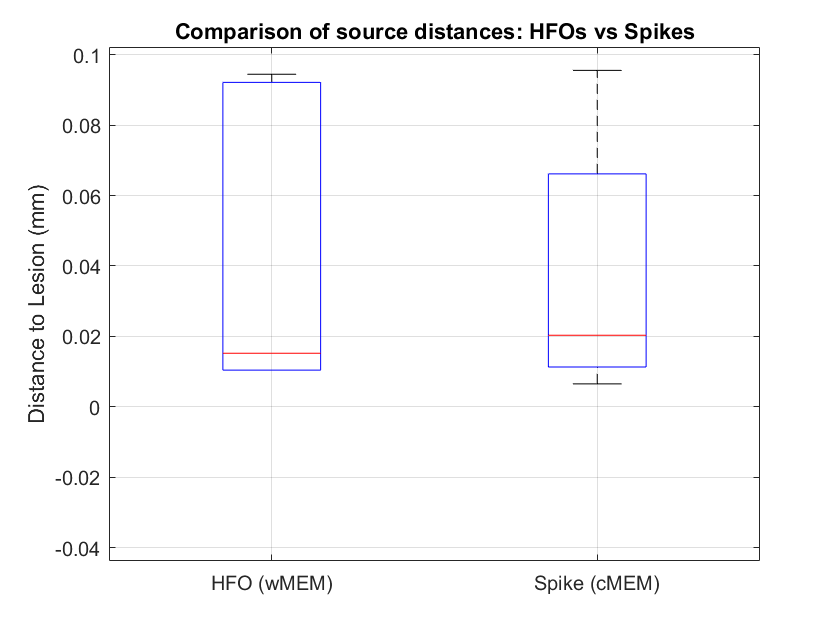

%p>0.05 means significance difference
%p<0.05 not significance difference

% Suponiendo que tienes:
% distances_HFO  = vector columna (distancias de HFOs)
% distances_spike = vector columna (distancias de spikes)


% Juntamos los datos y les damos etiquetas
all_data = [distances_HFO(:); distances_spike(:)];
group = [repmat({'HFO (wMEM)'}, length(distances_HFO), 1); ...
    repmat({'Spike (cMEM)'}, length(distances_spike), 1)];

% Boxplot
figure;
boxplot(all_data, group);
ylabel('Distance to Lesion (mm)');
title('Comparison of source distances: HFOs vs Spikes');
grid on;

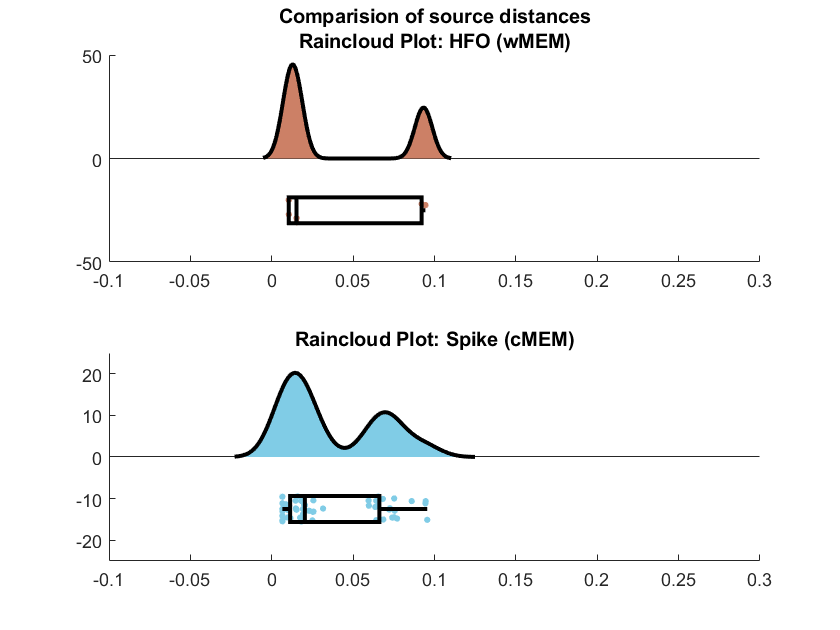

close all;
cb = [0.5 0.8 0.9; 1 1 0.7; 0.7 0.8 0.9; 0.8 0.5 0.4; 0.5 0.7 0.8; 1 0.8 0.5; 0.7 1 0.4; 1 0.7 1; 0.6 0.6 0.6; 0.7 0.5 0.7; 0.8 0.9 0.8; 1 1 0.4];
figure;
subplot(2, 1, 1)
h1 = raincloud_plot(distances_HFO(: ), 'box_on', 1, 'color', cb(4,:), 'bandwidth', .2, 'density_type', 'ks');
title(['Comparision of source distances' newline 'Raincloud Plot: HFO (wMEM)']);
set(gca, 'XLim', [-0.1 0.3]);
box off
subplot(2, 1, 2)
h2 = raincloud_plot(distances_spike(:), 'box_on', 1, 'color', cb(1,:), 'bandwidth', .2, 'density_type', 'ks');
title('Raincloud Plot: Spike (cMEM)');
set(gca, 'XLim', [-0.1 0.3]);
box off


Q1 = quantile(distances_HFO, 0.25);     % Primer cuartil (25%)
Q3 = quantile(distances_HFO, 0.75);     % Tercer cuartil (75%)
IQR = Q3 - Q1; %qué tan ancho en el 50% de mis datos  % Rango intercuartílico (cuaderadi azul)

% Límites de los bigotes (cualquier punto fuera de este limite se considera
% valores atipicos)
lower_bound = Q1 - 1.5 * IQR;
upper_bound = Q3 + 1.5 * IQR;
%El criterio de 1.5 veces el IQR es una convención estadística clásica usada para detectar valores atípicos (outliers) en un conjunto de datos.
%asume que la mayoría de los datos deberían estar cerca del centro (dentro del IQR)

outlier_mask = distances_HFO < lower_bound | distances_HFO > upper_bound;
outlier_values = distances_HFO(outlier_mask);
outlier_indices = find(outlier_mask);

fprintf('Outliers encontrados:\n');

Outliers encontrados:


for i = 1:length(outlier_values)
    fprintf('Índice: %d → Valor: %.4f mm\n', outlier_indices(i), outlier_values(i));
end

hfo_rate = (sum(distances_HFO==0))/length(distances_HFO)

hfo_rate = 0

spike_rate = (sum(distances_spike==0))/length(distances_spike)

spike_rate = 0

%Wilcoxon Rank sum test
[p,h,stats] = ranksum(SD_HFO, SD_spike)

p = 0.7730

h = logical
   0


stats = struct with fields:
       zval: 0.2884
    ranksum: 192


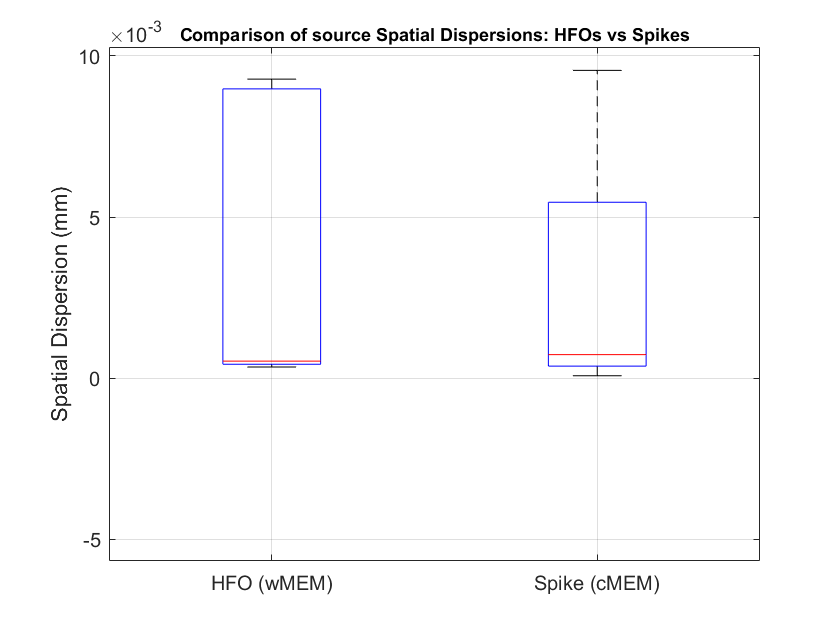

% Juntamos los datos y les damos etiquetas
all_data = [SD_HFO(:); SD_spike(:)];
group = [repmat({'HFO (wMEM)'}, length(SD_HFO), 1); ...
    repmat({'Spike (cMEM)'}, length(SD_spike), 1)];

% Boxplot
figure;
boxplot(all_data, group);
ylabel('Spatial Dispersion (mm)');
title('Comparison of source Spatial Dispersions: HFOs vs Spikes','FontSize',9);
grid on;

Now, let's obtein the Final Scout (Ward's herarquical clustering)

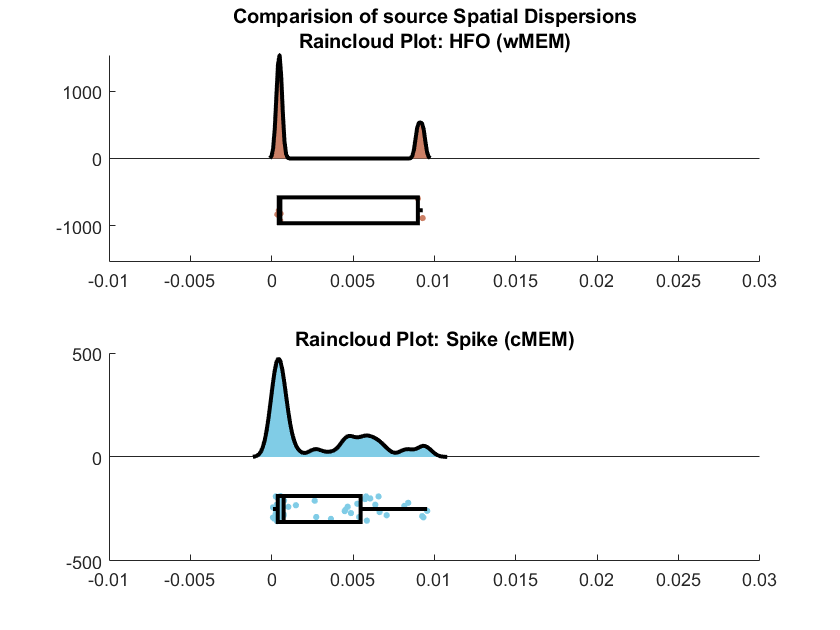

close all;
cb = [0.5 0.8 0.9; 1 1 0.7; 0.7 0.8 0.9; 0.8 0.5 0.4; 0.5 0.7 0.8; 1 0.8 0.5; 0.7 1 0.4; 1 0.7 1; 0.6 0.6 0.6; 0.7 0.5 0.7; 0.8 0.9 0.8; 1 1 0.4];
figure;
subplot(2, 1, 1)
h1 = raincloud_plot(SD_HFO(:), 'box_on', 1, 'color', cb(4,:), 'bandwidth', .2, 'density_type', 'ks');
title(['Comparision of source Spatial Dispersions' newline 'Raincloud Plot: HFO (wMEM)']);
set(gca, 'XLim', [-0.01 0.030]);
box off
subplot(2, 1, 2)
h2 = raincloud_plot(SD_spike(:), 'box_on', 1, 'color',cb(1,:), 'bandwidth', .2, 'density_type', 'ks');
title('Raincloud Plot: Spike (cMEM)');
set(gca, 'XLim', [-0.01 0.030]);
box off

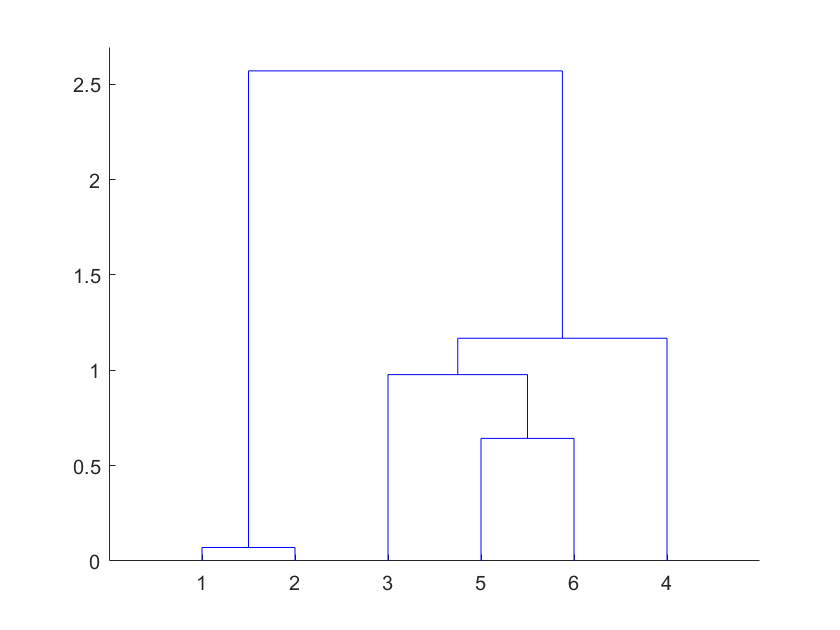


clear Z;
%HFOs
maps = HFO_sources_intensities;
maps_norm = {};
%Normalization of the maps with Frobenius
for i = 1:length(maps)
    maps_norm{i} = maps{i}/norm(maps{i},'fro');
end
% a = 1;
% for i = 7:12
%     maps_norm{a} = maps{i}/norm(maps{i},'fro');
%     a = a+1;
% end
% for i = 18:22
%     maps_norm{a} = maps{i}/norm(maps{i},'fro');
%     a = a+1;
% end

%Calculo de la correlación entre los mapas --> Matriz similitud
sim_matrix = zeros(length(maps_norm));
for i = 1:length(maps_norm)
    for j = 1:length(maps_norm)
        sim = abs(dot(maps_norm{i},maps_norm{j}));
        sim_matrix(i,j) = sim;
        sim_matrix(j,i) = sim;
    end
end

dissim_matrix = ones(size(sim_matrix,1), size(sim_matrix,2));
dissim_matrix = dissim_matrix - sim_matrix; % matriz de dissimilitud

%Clustering con Ward
Z = linkage((dissim_matrix),'ward'); %Z= (indice fusionado X Indice Fusionado X Distancia en la fusion)
figure;
dendrogram(Z);

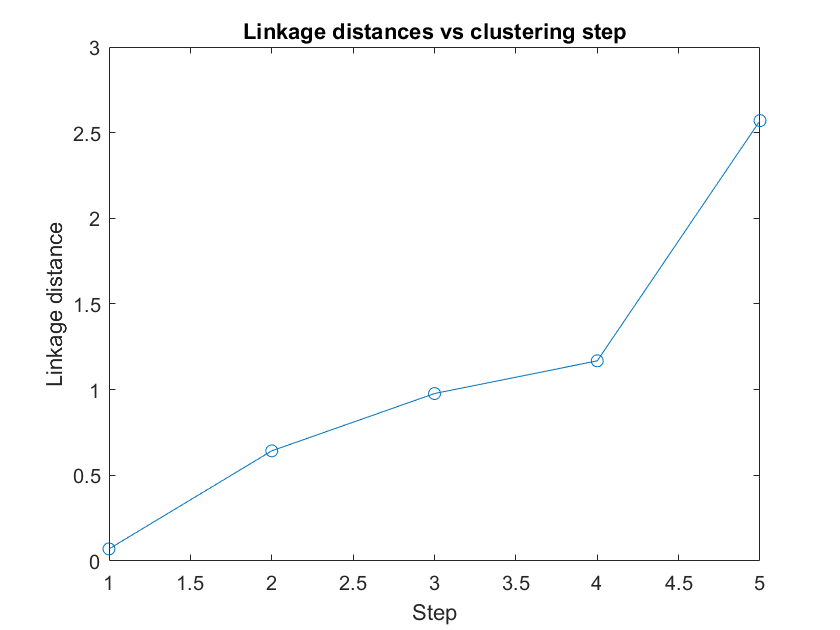

% Optional: Plot linkage distances
linkage_distances = Z(:,3);  % 3rd column = linkage distances
figure;
plot(1:length(linkage_distances), linkage_distances, '-o');
xlabel('Step');
ylabel('Linkage distance');
title('Linkage distances vs clustering step');

**📐 Eje X: ****Clustering Step**

- Cada punto representa una **fusión de dos grupos** (clusters) que hizo el algoritmo jerárquico (Ward).

- Comienza con **N grupos individuales** (1 por cada mapa de fuente), y termina cuando todos están agrupados en uno solo.

- Así que si tienes 33 mapas, habrá 32 pasos (33 → 32 → ... → 1).

**📏 Eje Y: ****Linkage Distance**

- Esto representa **cuán diferentes** eran los grupos que se están uniendo en ese paso.

- Específicamente, es una medida de **disimilitud** entre los dos clusters que se están fusionando.

📌 Cuanto **más alto** es el valor en Y, más **diferentes eran los grupos fusionados**.

Eso quiere decir:

- En ese **paso 15**, se fusionaron dos clusters que eran **distintos entre sí con una disimilitud de 1.0**.

- Si tú eliges cortar el dendrograma **antes de ese paso**, todos los clusters que existan en ese momento tendrían **menos disimilitud que 1.0** entre sus elementos.

## ✅ ¿Y cuántos clusters habría en el paso 15?

Dado que empezaste con 33 scouts y haces 15 fusiones:Clusters restantes=33−15=18\

Entonces, si tú cortas el dendrograma justo **antes del paso 15**, tendrías **18 clusters**.

## 🔍 ¿Qué debes buscar?

La clave está en encontrar el **“elbow”** (codo) o **salto grande** en la curva.**¿Por qué?**

- Las primeras fusiones son entre mapas **muy parecidos** → distancia pequeña.

- Luego, empieza a fusionar grupos **menos parecidos** → la distancia sube.

- El punto donde esa subida **cambia bruscamente** es donde deberías **detener el clustering**:→ ese es el **número óptimo de clusters**.


% Calcula la diferencia entre cada paso consecutivo
jumps = diff(linkage_distances);

% Encuentra el índice donde el salto es máximo
[~, elbow_step] = max(jumps);

% Calcula el número óptimo de clusters:
% Número inicial de elementos - número de fusiones hasta el codo
n_clusters = size(Z,1) - elbow_step + 1;

if isempty(n_clusters) == 1
    n_clusters = 1;
end
clusters = cluster(Z,'maxclust',n_clusters);
consensus_map_HFO = {};
% Promediar los mapas por cada cluster
for c = 1:n_clusters
    idx = find(clusters == c);
    cluster_maps = cat(2,maps{idx});
    consensus_map_HFO{c} = mean(cluster_maps,2);
end

for i = 1:n_clusters
    source = consensus_map_HFO{i};
    source = source/max(source);
    source = find(source>=0.8);

    consensus_scout_HFO(i).Vertices = source;
    consensus_scout_HFO(i).Seed = source(1);
    consensus_scout_HFO(i).Color = [1,1,1];
    consensus_scout_HFO(i).Label = ['Conceus_HFO_',num2str(i)];
    consensus_scout_HFO(i).Function = 'Mean';
    consensus_scout_HFO(i).Region = 'LF';
    consensus_scout_HFO(i).Handles = [];

end

for j = 1:n_clusters
    % ==== CONFIGURACIÓN ====
    scouts = consensus_scout_HFO(j); % Reemplaza con tu array de structs si es otro nombre
    save_name = ['Consensus_HFO_scout_', num2str(j),'.mat'];  % ¡IMPORTANTE! Debe contener "scout" en el nombre

    % ==== LIMPIEZA Y VALIDACIÓN ====
    for i = 1:length(scouts)
        % Corregir campos tipo celda
        if iscell(scouts(i).Label),    scouts(i).Label    = scouts(i).Label{1}; end
        if iscell(scouts(i).Region),   scouts(i).Region   = scouts(i).Region{1}; end
        if iscell(scouts(i).Function), scouts(i).Function = scouts(i).Function{1}; end

        % Asegurar color como vector fila
        if size(scouts(i).Color,1) > 1
            scouts(i).Color = scouts(i).Color(:)';
        end

        % Añadir campo Handles si falta
        if ~isfield(scouts(i), 'Handles')
            scouts(i).Handles = [];
        end
    end

    % ==== OBTENER NÚMERO DE VÉRTICES DEL CÓRTEX ====
    nb_vertices = size(sCortex.Vertices, 1);  % asegúrate que sCortex está cargado

    % ==== CREAR ATLAS ====
    Name =['Consensus_HFO_scout_', num2str(j),'.mat'];
    Scouts = scouts;
    TessNbVertices = nb_vertices;

    % ==== GUARDAR ATLAS EN FORMATO CORRECTO ====
    output_file = fullfile(folder_path, save_name);
    save(output_file, 'Name', 'Scouts', 'TessNbVertices');
end
a = 1;
for i = 1:n_clusters
    b = length(find(clusters==i));
    if b>a
        final_cluster = i;
        final_source = consensus_map_HFO{1,i};
        a = b;
    end
end
% final_source = consensus_map_HFO{1,2};
final_source_matrix = zeros(length(final_source),length(time));
for i = 1:size(final_source_matrix,2)
    final_source_matrix(:,i)=final_source;
end
%     aa.ImageGridAmp = final_source_matrix;


Compare with other sources 


% ImageGridAmp = ImageKernel (verticex x channels) * Average signal data
% (channels x time)
data = average_data.F;

Unable to resolve the name average_data.F.

data(end,:) = [];
data(end,:) = [];

% 2. Encontrar índice del tiempo t = 0
[~, t0_idx] = min(abs(MN_source.Time - 0));

% 3. Obtener las intensidades en fuente:
map_mn = MN_source.ImagingKernel * F(:, t0_idx);          % [15002 x 1]
map_bf = beamforming_source.ImagingKernel * F(:, t0_idx); % [15002 x 1]
map_dip = dipoles_source.ImagingKernel * F(:, t0_idx);    % [15002 x 1]
% final_source = column vector of my computed final souce with the HFOs

% I am going to compute the maximum of all the sources and compute its
% minimum distance to the lesion.

sources = {map_mn,map_bf,map_dip,final_source};

distances_sources = zeros(1,4);

for i = 1:length(sources)
    [max_value, max_idx] = max(abs(sources{1,i})); %the negative value just means that the dipole is pointing in other direction
    vertix_coord = vertice(max_idx,:);
    dist = sqrt(sum((region_coord - vertix_coord).^2,2));
    distances_sources(i) = min(dist);

end

SD_sources = zeros(1,4);

for j = 1:length(SD_sources)
    numerator = 0;
    denominator = 0;
    scout = (1:length(sources{1,j}));
    intensity_vector = abs(sources{1,j});
    for i = 1:length(scout)
        intensity_value = intensity_vector(scout(i));
        vertix_coord = vertice(i,:);
        dist = sqrt(sum((region_coord - vertix_coord).^2,2));
        dist_to_lesion = min(dist);
        numerator = numerator + ((dist_to_lesion.^2).*(intensity_value.^2));
        denominator = denominator + (intensity_value.^2);
    end
    SD_sources(j) = numerator/denominator;
end


names = {'Minimum Norm Imaging', ' Beamforming', 'Dipole Modeling', 'Maximum Entropy on the Mean (wMEM)'};
% Print the results in a latex table
% Define folder and LaTeX filename
%folder_path = fullfile(getenv('USERPROFILE'), 'Documents\CSIC\navidad\patient60\arrays'); % Windows
latex_filename = fullfile(folder_path, 'Sources_Mesurements.tex');

% Open file for writing
fid = fopen(latex_filename, 'w');

% Write LaTeX table header
fprintf(fid, '\\begin{table}[H]\n');
fprintf(fid, '\\centering\n');
fprintf(fid, '\\footnotesize\n');
fprintf(fid, '\\begin{tabular}{|c|c|c|}\n');
fprintf(fid, '\\hline\n');
fprintf(fid, 'Source Computation Method & Minimum distance (mm) & Spatial Dispersion (mm) \\\\\n');
fprintf(fid, '\\hline\n');

% Fill table with data

for i = 1:length(sources)
    label_print = names{i};
    dist_print = distances_sources(i);
    SD_print = SD_sources(i);
    % Write the table row
    fprintf(fid, '%s & $%.3e$ & $%.3e$ \\\\\n', ...
        label_print, dist_print, SD_print);
end

% Close table
fprintf(fid, '\\hline\n');
fprintf(fid, '\\end{tabular}\n');
fprintf(fid, '\\caption{Minimum distance and Spatial Dispersion with the epileptic area determined by the sources}\n');
fprintf(fid, '\\end{table}\n');

fclose(fid);